# visualizing b_sec at one time - 2d

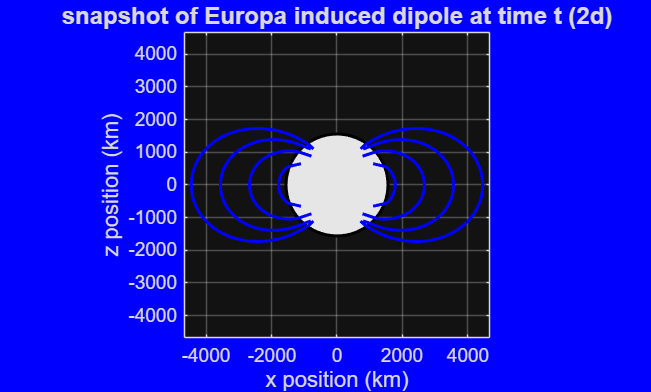

clear
% define constants

r_m = 1560; % Europa radius (km)
B_prim = 250; % approximate background field amplitude nT
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians (around 8 deg)
omega = 2*pi / (11.23 * 3600); % synodic freq. (rad/sec), 11.23 hr period

t = 0;

% inducing field direction
e0 = [0;0;1];

% create spatial grid (x-z plane)
grid_limit = 3 * r_m; % view up to 3 planetary radii out 
[X,Z] = meshgrid(linspace(-grid_limit, grid_limit, 30), ...
    linspace(-grid_limit,grid_limit, 30));

Y = zeros(size(X)); % slicing through y=0

% compute secondary field components (bx,by,bz) at every point 
% initialize arrays to hold magnetic field vector components

Bx_spatial = zeros(size(X));
By_spatial = zeros(size(X));
Bz_spatial = zeros(size(X));

% loop through each grid point to calculate the spatial part of eqn (3)
for i = 1:numel(X);

    % define position vector r from center of moon
    r_vec = [X(i); Y(i); Z(i)];
    r = norm(r_vec);

    % mask field inside the moon to avoid division by 0
    if r < r_m;
        continue;
    end

    % calculate dot prod (r . e0)
    r_dot_e0 = dot(r_vec, e0);

    % evaluate spatial vector bracket: 3*(r . e0)*r - (r^2)*e0
    spatial_bracket = 3 * r_dot_e0 * r_vec - (r^2) * e0;

    % compute spatial coefficient: - (A * B_prim * r_m^3) / (2 * r^5)
    coef = - (A *B_prim * r_m^3) / (2 *r^5);

    % store vector components
    B_vector = coef * spatial_bracket;
    Bx_spatial(i) = B_vector(1);
    By_spatial(i) = B_vector(2);
    Bz_spatial(i) = B_vector(3);    

end


% single snapshot setup

% time factor (t=0 here anyway)
time_factor = cos(omega * t - phi);

% apply scalar factor to pre-calculated spatial field components
Bx = Bx_spatial * time_factor;
Bz = Bz_spatial * time_factor;

% create static figure
figure('Color','b');
hold on;

% draw Europa as filled circle
rectangle('Position',[-r_m, -r_m, 2*r_m, 2*r_m], 'Curvature', [1,1], ...
    'FaceColor', [0.9 0.9 0.9], 'EdgeColor','k', 'LineWidth', 1.5);

% seeds of the streamlines
seed_z = zeros(1, 15);
seed_x = linspace(-4*r_m, 4*r_m, 15);

% plot mag field vectors
h1 = streamline(X,Z,Bx,Bz,seed_x, seed_z);
h2 = streamline(X,Z,-Bx,-Bz,seed_x, seed_z);


set(h1, 'Color', 'b', 'LineWidth', 1.5);
set(h2, 'Color', 'b', 'LineWidth', 1.5);

% grid formatting
axis equal; 
xlim([-grid_limit, grid_limit]);
ylim([-grid_limit, grid_limit]);
xlabel('x position (km)', 'FontSize', 11);
ylabel('z position (km)', 'FontSize', 11);
title('snapshot of Europa induced dipole at time t (2d)', 'FontSize', 12);
grid on;
box on;



% magnetic dipole always aligns itself with the field that created it
% in this case, e0 = [0,0,1], so r . e0 = z

